# Results Ablation Study

clc;
clear all;
close all;



total_iteration = 1

Wireless packet type: SC


N_x = 4

N = 16

M_x = 15

M_y = 15

zeta = 0.9800

T_coh = 0.0038

N_packets_coh = 12

T_x = 50

SNR_dB = 36.5005

EnvPars = struct with fields:
              channelModel: 'rician_los'
                    fc_GHz: 28
                    V_hall: 1000
                    S_hall: 600
                   mu_lgDS: -7.5916
                sigma_lgDS: 0.1500
                  mu_lgASD: 1.5600
               sigma_lgASD: 0.2500
                  mu_lgASA: 1.5168
               sigma_lgASA: 0.3755
                  mu_lgZSA: 1.2075
               sigma_lgZSA: 0.3500
                  mu_lgZSD: 1.3500
               sigma_lgZSD: 0.3500
                   mu_K_dB: 7
                sigma_K_dB: 8
                        KR: 24.5323
                      rTau: 2.7000
                 mu_XPR_dB: 12
              sigma_XPR_dB: 6
    clusterShadowingStd_dB: 4
                        Nc: 25
                      Mray: 20
            clusterASD_deg: 5
            clusterASA_deg: 8
            clusterZSA_deg: 9
            rayOffsetAlpha: [-0.0447 0.0447 -0.1413 0.1413 -0.2492 0.2492 -0.3715 0.3715 -0.5129 0.5129 -0.6


%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\SIM\code




Parameters

%% ---- 1. Discover checkpoint directories ----
dataset_path = fullfile('..', 'Dataset');
ckpt_dirs = dir(fullfile(dataset_path, 'ablation_Nx_5_ckpt_zeta_*'));
ckpt_dirs = ckpt_dirs([ckpt_dirs.isdir]);   % keep directories only
 
if isempty(ckpt_dirs)
    error('No ablation_ckpt_zeta_* directories found in %s.\nRun the ablation script first.', dataset_path);
end
 
fprintf('Found %d zeta checkpoint director%s:\n', numel(ckpt_dirs), ...
    ternary(numel(ckpt_dirs)==1,'y','ies'));

Found 3 zeta checkpoint directories:


for d = 1:numel(ckpt_dirs)
    fprintf('  %s\n', ckpt_dirs(d).name);
end

  ablation_Nx_5_ckpt_zeta_0.986
  ablation_Nx_5_ckpt_zeta_0.988
  ablation_Nx_5_ckpt_zeta_0.990


 
%% ---- 2. Parse zeta value from directory name and load all combos ----
% Directory name format: ablation_ckpt_zeta_X.XXX
% Re-use whatever lambda the first checkpoint file reports (all should agree).
 
rows = {};   % will grow as we load; converted to table at the end
 
for d = 1:numel(ckpt_dirs)
    dir_name   = ckpt_dirs(d).name;
    zeta_str   = strrep(dir_name, 'ablation_Nx_5_ckpt_zeta_', '');
    zeta_val   = str2double(zeta_str);
    if isnan(zeta_val)
        warning('Could not parse zeta from directory name "%s" -- skipping.', dir_name);
        continue;
    end
 
    % combo_files = dir(fullfile(dir_name, 'combo_*.mat'));
    combo_files = dir(fullfile(dataset_path, dir_name, 'combo_*.mat'));
    if isempty(combo_files)
        fprintf('  %s: no completed combos yet, skipping.\n', dir_name);
        continue;
    end
    fprintf('  %s: %d completed combo(s) found.\n', dir_name, numel(combo_files));
 
    for f = 1:numel(combo_files)
        C = load(fullfile(combo_files(f).folder, combo_files(f).name));
        rows{end+1} = [C.T_SIM_cur, C.L_cur, C.M_cur, C.s_x_cur, ...
                       zeta_val, C.loss_final];  %#ok<SAGROW>
    end
end

  ablation_Nx_5_ckpt_zeta_0.986: 56 completed combo(s) found.
  ablation_Nx_5_ckpt_zeta_0.988: 55 completed combo(s) found.
  ablation_Nx_5_ckpt_zeta_0.990: 55 completed combo(s) found.


 
if isempty(rows)
    error('No completed combos found across all checkpoint directories.');
end
 
%% ---- 3. Assemble table ----
mat = cell2mat(rows.');   % n_rows x 6
results_all = table(mat(:,1), mat(:,2), mat(:,3), mat(:,4), mat(:,5), mat(:,6), ...
    'VariableNames', {'T_SIM','L','M','s_x','zeta','loss_final'});
 
fprintf('\nTotal rows loaded: %d (across %d zeta value(s))\n', ...
    height(results_all), numel(unique(results_all.zeta)));


Total rows loaded: 166 (across 3 zeta value(s))


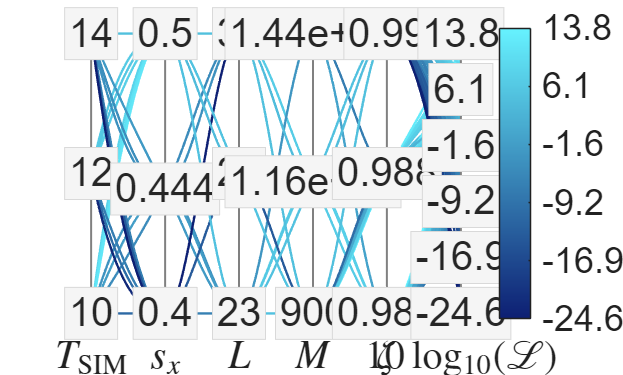

 
%% ---- 4. Build display table (normalise units) ----
results_disp           = results_all;
results_disp.T_SIM     = results_all.T_SIM / lambda;   % units of lambda
results_disp.s_x       = results_all.s_x   / lambda;   % units of lambda
 
%% ---- 5. Color mapping (loss-encoded, same blue gradient) ----
nColors          = 256;
dark_blue        = [0.05, 0.12, 0.45];
bright_light_blue = [0.40, 0.95, 1.00];
custom_blue_cmap = [linspace(dark_blue(1), bright_light_blue(1), nColors)', ...
                    linspace(dark_blue(2), bright_light_blue(2), nColors)', ...
                    linspace(dark_blue(3), bright_light_blue(3), nColors)'];
 
loss_min     = min(results_disp.loss_final);
loss_max     = max(results_disp.loss_final);
log_loss     = 10*log10(results_disp.loss_final);
log_loss_min = 10*log10(loss_min);
log_loss_max = 10*log10(loss_max);
% Color index on log scale so small-loss combos get well-separated colours
color_idx = round(1 + (nColors-1) * (log_loss - log_loss_min) / (log_loss_max - log_loss_min));
 
%% ---- 6. Build 6-column normalised matrix for parallel coordinates ----
% Column order: T_SIM/lam | L | M | s_x/lam | zeta | Loss
plot_matrix = [results_disp.T_SIM, results_disp.s_x, results_disp.L,...
               results_disp.M, results_disp.zeta, 10*log10(results_disp.loss_final)];
 
min_vals  = min(plot_matrix,  [], 1);
max_vals  = max(plot_matrix,  [], 1);
norm_mat  = (plot_matrix - min_vals) ./ (max_vals - min_vals);
 
n_axes    = 6;
x_orig    = 1:n_axes;
x_fine    = linspace(1, n_axes, 300);
 
%% ---- 7. Plot ----
figure; hold on;
 
% Background splines (one per combo)
for i = 1:size(norm_mat, 1)
    y_fine = pchip(x_orig, norm_mat(i,:), x_fine);
    plot(x_fine, y_fine, ...
        'Color', [custom_blue_cmap(color_idx(i),:), 0.35], ...
        'LineWidth', 1.2);
end
 
% Vertical axis lines
for x = 1:n_axes
    line([x x], [0 1], 'Color', [0.5 0.5 0.5], 'LineWidth', 1.0);
end
 
% Tick labels with background boxes
ticks_T    = unique(results_disp.T_SIM);
ticks_L    = unique(results_disp.L);
ticks_M    = unique(results_disp.M);
ticks_s    = unique(results_disp.s_x);
ticks_z    = unique(results_disp.zeta);
ticks_loss = 10.^(linspace(log10(loss_min), log10(loss_max), 6));   % original scale, evenly spaced in dB
tick_values_cell = {ticks_T, ticks_s, ticks_L, ticks_M, ticks_z, ticks_loss};
 
for x = 1:n_axes
    raw_ticks  = tick_values_cell{x};
    if x == n_axes   % loss axis: plot_matrix col is log10(loss), ticks are original scale
        norm_ticks = (10*log10(raw_ticks) - min_vals(x)) / (max_vals(x) - min_vals(x));
    else
        norm_ticks = (raw_ticks - min_vals(x)) / (max_vals(x) - min_vals(x));
    end
    for t = 1:numel(norm_ticks)
        if x == n_axes
            db_val = 10*log10(raw_ticks(t));
            label_str  = sprintf('%.1f', db_val);
            tick_interp = 'none';
        else
            label_str  = num2str(raw_ticks(t), '%.3g');
            tick_interp = 'none';
        end
        text(x, norm_ticks(t), label_str, ...
            'FontSize', font, ...
            'Color', [0.15 0.15 0.15], ...
            'BackgroundColor', [0.96 0.96 0.96], ...
            'EdgeColor',  [0.85 0.85 0.85], ...
            'Margin', 2, ...
            'Interpreter',         tick_interp, ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment',   'middle');
    end
end
 
% X-axis labels (LaTeX)
latex_labels = {'$$\frac{T_\mathrm{SIM}}{\lambda}$$', '$$\frac{s_x}{\lambda}$$',...
                '$$L$$', '$$M$$', '$$\zeta$$', '$$10\log_{10}(\mathcal{L})$$'};
for x = 1:n_axes
    text(x, -0.06, latex_labels{x}, ...
        'Interpreter',       'latex', ...
        'FontSize',          font, ...
        'HorizontalAlignment','center', ...
        'VerticalAlignment', 'top');
end
 
hold off;
 
xlim([0.7, n_axes + 0.3]);
ylim([-0.02, 1.02]);
set(gca, 'Box',    'off', ...
         'XColor', 'none', ...
         'YColor', 'none', ...
         'FontSize', font);
 
colormap(custom_blue_cmap);
c = colorbar;
clim([log_loss_min, log_loss_max]);
cb_log_ticks = linspace(log_loss_min, log_loss_max, 6);
c.Ticks      = cb_log_ticks;
c.TickLabels = arrayfun(@(v) sprintf('%.1f', v), cb_log_ticks, 'UniformOutput', false);

#### ANOVA


%% ===================== 4. Sensitivity ranking via N-way ANOVA =====================
if license('test', 'Statistics_Toolbox')
    [p, tbl, stats] = anovan(results_disp.loss_final, ...
        {results_disp.T_SIM, results_disp.L, results_disp.M, results_disp.s_x}, ...
        'model',    'interaction', ...
        'varnames', {'T_SIM','L','M','s_x'}, ...
        'display',  'off');

    % ---- Extract rows from tbl (skip header row 1, Error and Total at end) ----
    % tbl columns: {Source, SS, df, Singular?, MS, F, p}
    n_rows   = size(tbl, 1);
    term_rows = 2 : n_rows-2;   % excludes header, Error, Total

    sources  = tbl(term_rows, 1);
    SS_vals  = cell2mat(tbl(term_rows, 2));
    df_vals  = cell2mat(tbl(term_rows, 3));
    F_vals   = cell2mat(tbl(term_rows, 6));
    p_vals   = cell2mat(tbl(term_rows, 7));

    % ---- SS for Total (last row) ----
    SS_total = cell2mat(tbl(end, 2));

    % ---- eta-squared: proportion of total variance explained ----
    eta2 = SS_vals / SS_total * 100;   % in percent

    % ---- Sort by SS descending ----
    [SS_sorted, sort_idx] = sort(SS_vals, 'descend');
    sources_sorted = sources(sort_idx);
    df_sorted      = df_vals(sort_idx);
    F_sorted       = F_vals(sort_idx);
    p_sorted       = p_vals(sort_idx);
    eta2_sorted    = eta2(sort_idx);

    % ---- Print ranked table ----
    fprintf('\n%-15s  %8s  %10s  %4s  %10s  %12s\n', ...
        'Source', 'eta^2 (%)', 'SS', 'df', 'F', 'p-value');
    fprintf('%s\n', repmat('-', 1, 70));
    for k = 1:numel(sort_idx)
        sig = '';
        if p_sorted(k) < 0.001,  sig = '***';
        elseif p_sorted(k) < 0.01,  sig = '**';
        elseif p_sorted(k) < 0.05,  sig = '*';
        else,                        sig = 'n.s.';
        end
        fprintf('%-15s  %7.2f%%  %10.2f  %4d  %10.4f  %12.4e  %s\n', ...
            sources_sorted{k}, eta2_sorted(k), SS_sorted(k), df_sorted(k), ...
            F_sorted(k), p_sorted(k), sig);
    end
    fprintf('%s\n', repmat('-', 1, 70));
    fprintf('%-15s  %10.2f  %4d\n', 'Total', SS_total, cell2mat(tbl(end,3)));
    fprintf('\nSignificance codes: *** p<0.001  ** p<0.01  * p<0.05  n.s. p>=0.05\n');
    fprintf('eta^2 = SS_term / SS_total (effect size, higher = more influential)\n');

    % ---- Save ranked results as a workspace table for downstream use ----
    anova_ranked = table( ...
        sources_sorted,  ...
        SS_sorted,       ...
        df_sorted,       ...
        F_sorted,        ...
        p_sorted,        ...
        eta2_sorted,     ...
        'VariableNames', {'Source','SS','df','F','p_value','eta2_pct'});
    % eta2_pct: eta^2 expressed as percentage of SS_total
    fprintf('\nResults saved in workspace variable: anova_ranked\n');

else
    warning('Statistics and Machine Learning Toolbox not found -- skipping ANOVA.');
end

%% ---- 1b. Ground-truth check: don't trust colors, read the actual rows ----
% Most reliable answer to "which direction should each parameter move":
% just sort by loss_final and look at the extremes directly.
sorted_results = sortrows(results_disp, 'loss_final');
fprintf('\n--- 10 BEST combos (lowest loss) ---\n');
disp(sorted_results(1:10, {'T_SIM','s_x','L','M','loss_final'}));
fprintf('\n--- 10 WORST combos (highest loss) ---\n');
disp(sorted_results(end-9:end, {'T_SIM','s_x','L','M','loss_final'}));

%% ---- 1b. Ground-truth check: don't trust colors, read the actual rows ----
% Most reliable answer to "which direction should each parameter move":
% just sort by loss_final and look at the extremes directly.
sorted_results = sortrows(results_disp, 'loss_final');
fprintf('\n--- 10 BEST combos (lowest loss) ---\n');
disp(sorted_results(1:10, {'T_SIM','s_x','L','M','loss_final'}));
fprintf('\n--- 10 WORST combos (highest loss) ---\n');
disp(sorted_results(end-9:end, {'T_SIM','s_x','L','M','loss_final'}));



function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function out = ternary(cond, a, b)
    if cond, out = a; else, out = b; end
end